# MSc Project IIS1 | BWFLnet_Water Analysis

#### Prepared by: Yuanfei Wang

#### Date: 17 July 2022

clc
clear
close all

### Model Setup and Initialisation

Initialisation of EPANET Matlab toolkit and loading of .net file.

epanet_path = 'E:\Program Files\MATLAB\R2021b\toolbox\epanet\EPANET-Matlab-Toolkit-master';
net_id = 'BWFLnet_MSc_2022_calibrated';
run( [epanet_path,'\start_toolkit'])

EPANET-MATLAB Toolkit Paths Loaded.


net = epanet([net_id,'.inp']);

EPANET version {20200} loaded (EMT version {v2.2.0}).
Loading File "BWFLnet_MSc_2022_calibrated.inp"...
Input File "BWFLnet_MSc_2022_calibrated.inp" loaded sucessfuly.


load("wq_data.mat");

### Network Data Loading

Load general network data, noting that this network has already been hydraulically calibrated, thus we can directly perform the quality analysis.

% Save element count variables
nn = net.NodeJunctionCount;
n0 = net.NodeReservoirCount;
np = net.LinkCount; % count of pipes and valves
D = net.getLinkDiameter';

% Save node and link index vectors
Reservoir_Idx = net.getNodeReservoirIndex;
Junction_Idx = net.getNodeJunctionIndex;
Link_Idx = double(net.getLinkIndex);

% Specify hydraulic and quality time steps (in seconds)
net.setTimeQualityStep(15*60); % 15 minute quality time steps
net.setTimeHydraulicStep(15*60); % 15 minute hydraulic time steps
nt = net.getTimeSimulationDuration./3600; % number of time steps in hours
days = 7; % simulation duration in days
net.setTimeSimulationDuration(nt*3600*days/7); % Set the simulation duration by changing days
nt = net.getTimeSimulationDuration./3600; % get the new nt


### Graph Creation Preparation

Use graph theory to plot network connectivity and spatial coordinates.

% Create A12 and A10 incidence matrices
LinkNodesList = net.getLinkNodesIndex;

A = zeros(np,nn+n0);
for k=1:np
    i = LinkNodesList(k,1);
    j = LinkNodesList(k,2);
    A(k,i) = -1;
    A(k,j) = 1;
end

A12 = A(:,Junction_Idx);
A10 = A(:,Reservoir_Idx);
A12 = sparse(A12);
A10 = sparse(A10);

% Obstain node XY and elevation information
XY = zeros(nn+n0,2);
XY(:,1) = net.getNodeCoordinates{1};
XY(:,2) = net.getNodeCoordinates{2};
elev = double(net.getNodeElevations(Junction_Idx))';

% Create adjacency matrix
A = [A12,A10];
AdjA = sparse(size(A,2),size(A,2));

for k = 1:size(A,1)
    node_in = find(A(k,:) == -1);
    node_out = find(A(k,:) == 1);
    AdjA(node_in,node_out) = 1;
    AdjA(node_out,node_in) = 1;
end
gr = graph(AdjA);

### Chlorine Simulation

Setup general chemical simulation parameters.

% Initialise EPANET simulation type
net.setQualityType('Chemical','mg/L');
net.setNodeSourceQuality(1:nn+n0,zeros(nn+n0,1)); % set all node source quality to zero

% Load the water quality data
Junction_SelectIdx = net.getNodeIndex(wq_data.node_ids([1,4,7,9]));
c_nodes_hydrantObs = wq_data.chlorine([2,5,8],:);
Junction_HydrantIdx = net.getNodeIndex(wq_data.node_ids([2,5,8]));
cext = wq_data.chlorine([3,6],:);

Assign chlorine decay parameters.

% Link bulk reaction coefficients
lambda = 0.5*ones(np,1); % units of days^-1
net.setLinkBulkReactionCoeff(1:np, -lambda);
net.setOptionsPipeBulkReactionOrder(1);

% Link wall decay reaction coefficients... apply by pipe size for S&G?
% theta = ones(np,1); % units of m/day
% for k = 1:np
%     if D(k) <= 75
%         theta(k) = 0.25;
%     elseif D(k) > 75 && D(k) <= 150
%         theta(k) = 0.175;
%     elseif D(k) > 150 && D(k) <= 250
%         theta(k) = 0.1;
%     else
%         theta(k) = 0.05;
%     end
% end
% 
% net.setLinkWallReactionCoeff(1:np, -theta);
% net.setOptionsPipeWallReactionOrder(1);

% Initial concentrations at nodes (mg/L)
c0 = zeros(nn+n0,nt);
net.setNodeInitialQuality(net.NodeIndex,c0);

% % Assign source chlorine with time varying pattern
% cext = ones(n0,nt);
% 
% % Constant source concentration for n0 reservoirs
% % cext = cext*0.25;
% 
% % Varying source concentration by source element
% source_c = [1.00, 0.85];

% for j = 1:n0
%     cext(j,:) = source_c(j)*cext(j,:);
% end

% Varying source concentration by source element with
% concentration spike (pulse) at t = 12
% t = 144;
% for i = 1:4*days*nt
%     for j = 1:n0
%         if i == t
%             cext(j,i) = 1*cext(j,i); % Pulse of 1 mg/L
%         else
%             cext(j,i) = source_c(j)*cext(j,i);
%         end
%     end
% end

base_cext = ones(n0,1); 
pattern_cext = cext./(base_cext*ones(1,size(cext,2))); % extend vector over nt columns 

% For loop to assign new patterns to source contrations at reservoirs and
% source type
for i=1:n0
    patternId = sprintf('Res_C_%d',i);
    net.addPattern(patternId,pattern_cext(i,:));
    net.setNodeSourcePatternIndex(net.NodeReservoirIndex(i),net.getPatternIndex(patternId));
    net.setNodeSourceQuality(net.NodeReservoirIndex(i),base_cext(i));
    net.setNodeSourceType(net.NodeReservoirIndex(i),'CONCEN');  
end

### Results from EPANET Simulation

Simulate hydraulic and quality analyses using EPANET's solvers.

hydraulic_res = net.getComputedHydraulicTimeSeries;
quality_res = net.getComputedQualityTimeSeries;

% Assign hydraulic results to network elements
h = hydraulic_res.Head(1:1+4*nt,1:nn).';
q = 1e-3*hydraulic_res.Flow(1:1+4*nt,:).';

% Assign quality results to network elements
c_nodes = quality_res.NodeQuality';
c_pipes = quality_res.LinkQuality';

% Get the simulated and observed data
c_nodes_Sim = c_nodes(Junction_SelectIdx,:);
c_nodes_Sim = c_nodes_Sim(:,2:end);

c_nodes_HydrantSim = c_nodes(Junction_HydrantIdx,:);
c_nodes_HydrantSim = c_nodes_HydrantSim(:,2:end);

c_nodes_Obs = wq_data.chlorine([1,4,7,9],:);
c_nodes_HydrantObs = wq_data.chlorine([2,5,8],:);

### Data Preparation

Prepare data for the trial-and-error calibration. Plot the chlorine concentration for visualisation.

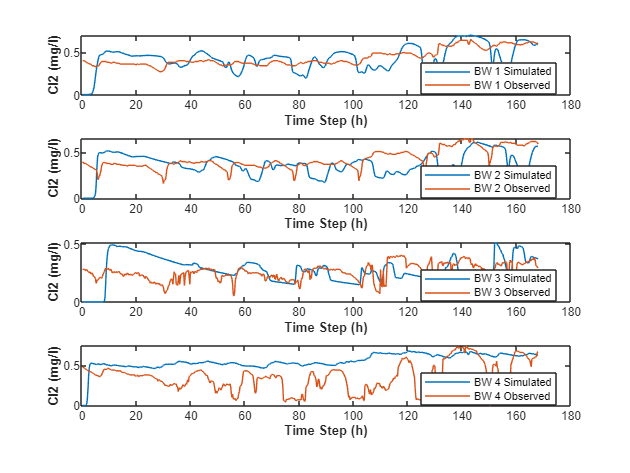

% create the plot for nodes at mains
for i = 1:length(Junction_SelectIdx)
    Junction_Name{i} = sprintf('BW %d',i);
end

% create the plot for hydrants
for i = 1:length(Junction_HydrantIdx)
    Junction_Hydrant_Name{i} = sprintf('BWH %d',i);
end

% Plot the quality of nodes in the main
figure,
for i = 1:length(Junction_SelectIdx)
    subplot(length(Junction_SelectIdx),1,i);
    plot(0.25:0.25:days*24,c_nodes_Sim(i,:),'-');
    hold on
    plot(0.25:0.25:days*24,c_nodes_Obs(i,:),'-');
    legend([Junction_Name{i},' Simulated'], [Junction_Name{i},' Observed'],'location','best');
    xlabel('Time Step (h)','fontweight','bold')
    ylabel('Cl2 (mg/l)','fontweight','bold')
end

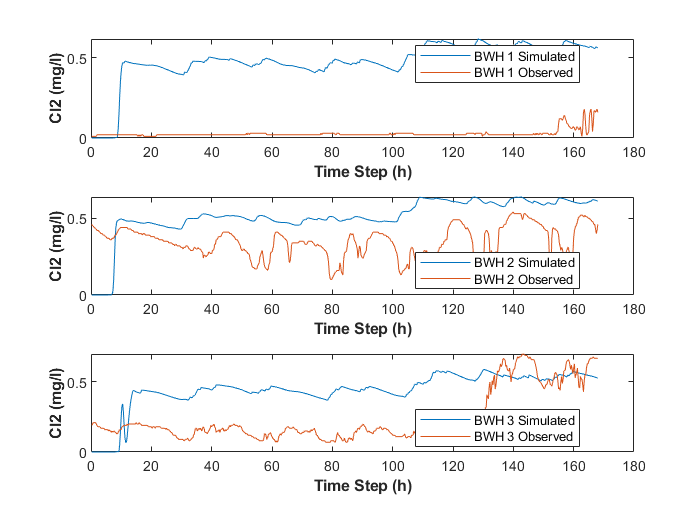

figure,
for i = 1:length(Junction_HydrantIdx)
    subplot(length(Junction_HydrantIdx),1,i);
    plot(0.25:0.25:days*24,c_nodes_HydrantSim(i,:),'-');
    hold on
    plot(0.25:0.25:days*24,c_nodes_HydrantObs(i,:),'-');
    legend([Junction_Hydrant_Name{i},' Simulated'], [Junction_Hydrant_Name{i},' Observed'],'location','best');
    xlabel('Time Step (h)','fontweight','bold')
    ylabel('Cl2 (mg/l)','fontweight','bold')
end

Get the roughness bsed pipe group.

R = net.getLinkRoughnessCoeff;
R_Group1 = [];R_Group2 = [];R_Group3 = [];R_Group4 = [];R_Group5 = [];R_Group6 = [];
R_Group7 = [];R_Group8 = [];R_Group9 = [];R_Group10 = [];R_Group11 = [];
R_CData = zeros(1,np);
for i = 1:np
    if abs(R(i) - 0) <= 0.01
        R_Group1 = [R_Group1,i];
        R_CData(i) = 1;
    elseif abs(R(i) - 0.1000) <= 0.01
        R_Group2 = [R_Group2,i];
        R_CData(i) = 2;
    elseif abs(R(i) - 0.1399) <= 0.01
        R_Group3 = [R_Group3,i];
        R_CData(i) = 3;
    elseif abs(R(i) - 1.5267) <= 0.01
        R_Group4 = [R_Group4,i];
        R_CData(i) = 4;
    elseif abs(R(i) - 2.1576) <= 0.01
        R_Group5 = [R_Group5,i];
        R_CData(i) = 5;
    elseif abs(R(i) - 9.0114) <= 0.01
        R_Group6 = [R_Group6,i];
        R_CData(i) = 6;
    elseif abs(R(i) - 10.3677) <= 0.01
        R_Group7 = [R_Group7,i];
        R_CData(i) = 7;
    elseif abs(R(i) - 11.6809) <= 0.01
        R_Group8 = [R_Group8,i];
        R_CData(i) = 8;
    elseif abs(R(i) - 14.8687) <= 0.01
        R_Group9 = [R_Group9,i];
        R_CData(i) = 9;
    elseif abs(R(i) - 16.2377) <= 0.01
        R_Group10 = [R_Group10,i]; 
        R_CData(i) = 10;
    else
        R_Group11 = [R_Group11,i];
        R_CData(i) = 11;
    end
end
R_Group = {R_Group1,R_Group2,R_Group3,R_Group4,R_Group5,R_Group6,R_Group7,R_Group8,R_Group9,...
    R_Group10,R_Group11};


According to the water age analysis, the longest water age before periodic behaviour is approxiamately 40 hours, thus we split the data into three parts, the first part is a 2-day stabilisation period, the second part is a 1-day train data, the last part is the 4-day validation time.

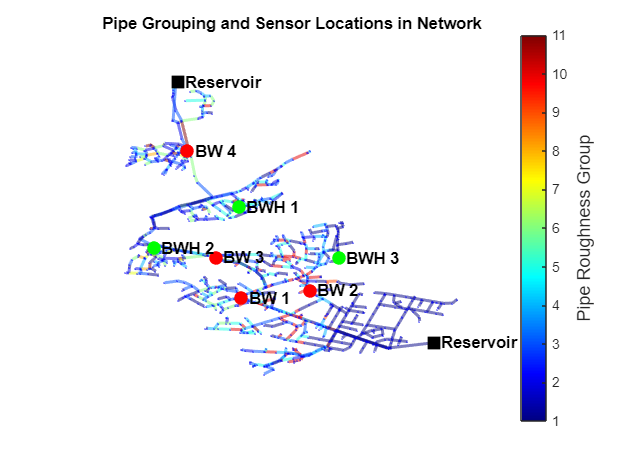

% Data splitting
Sim_train = c_nodes_Sim(:,2*96+1:3*96);
Sim_val = c_nodes_Sim(:,3*96+1:end);
Obs_train = c_nodes_Obs(:,2*96+1:3*96);
Obs_val = c_nodes_Obs(:,3*96+1:end);
mse_function = @(sim,obs) (1/size(obs,1)/size(obs,2))*sum(sum((sim - obs).^2));

% Plot the sensor location on the network map
figure
p1 = plot(gr);
p1.XData = XY(:,1);
p1.YData = XY(:,2);
p1.LineWidth = 2;
p1.EdgeColor = 'k';
p1.MarkerSize = 0.01;
p1.NodeColor = 'b';
p1.NodeLabel = '';
highlight(p1,Junction_SelectIdx,'NodeColor','r','MarkerSize',8);
labelnode(p1,Junction_SelectIdx,Junction_Name);
highlight(p1,Junction_HydrantIdx,'NodeColor','g','MarkerSize',8);
labelnode(p1,Junction_HydrantIdx,Junction_Hydrant_Name);
highlight(p1,Reservoir_Idx,'NodeColor','k','Marker','s','MarkerSize',10);
labelnode(p1,Reservoir_Idx,{'Reservoir','Reservoir'});
p1.NodeFontSize = 11;
p1.NodeLabelColor = 'k';
p1.NodeFontWeight = 'bold';
p1.EdgeFontSize = 11;
p1.EdgeLabelColor = 'k';
p1.EdgeFontWeight = 'bold';
p1.EdgeCData = R_CData;
hcb_R = colorbar;
colormap('jet');
hcb_R.Label.String = 'Pipe Roughness Group';
hcb_R.Label.FontSize = 12;
axis('off')
title('Pipe Grouping and Sensor Locations in Network')

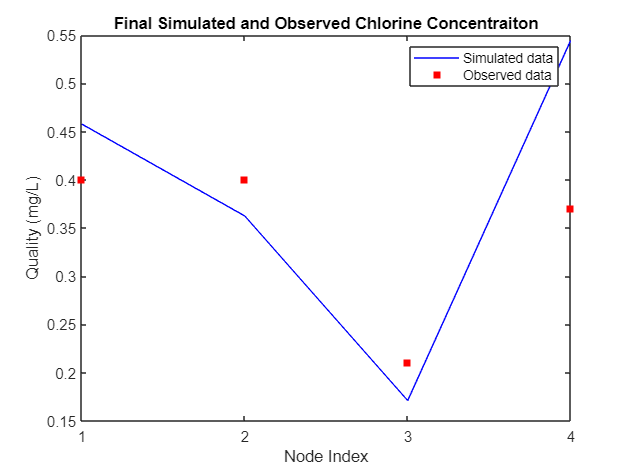

% Plot the calibrated quality-time figure
figure,
plot(1:size(c_nodes_Obs,1),Sim_train(:,end),'-b')
hold on
scatter(1:size(c_nodes_Obs,1),Obs_train(:,end),'red','filled','square')
legend({'Simulated data','Observed data'})
xlabel('Node Index')
ylabel('Quality (mg/L)')
xticks(1:1:size(c_nodes_Obs,1));
title('Final Simulated and Observed Chlorine Concentraiton')

### Trial-and-Error calibration (No group)

The trial and error calibration is a step by step process, we divide the network into pipe groups and manually adjust the decay coefficient of pipes upstream of the sensors to minimize the deviation between simulated and observed data.

% Consider the whole network together and assign the same decay parameter
mse_before = mse_function(Sim_train,Obs_train);
Tol = 1e-3;

% tic;
% for i = 1:Iter
%     net.setLinkBulkReactionCoeff(1:np, -lambda_NoGroup);
%     qual_NoGroup = net.getComputedQualityTimeSeries;
%     c_nodes_Sim_NoGroup = qual_NoGroup.NodeQuality';
%     Sim_NoGroup = c_nodes_Sim_NoGroup(Junction_SelectIdx,2:end);
%     Sim_NoGroup = Sim_NoGroup(:,2*96+1:3*96);
%     mse_NoGroup(i) = mse_function(Sim_NoGroup,Obs_train);
%     if mse_NoGroup(i) < Tol
%         break;
%     else
%         lambda_NoGroup = lambda_NoGroup + 0.1;
%     end 
% end
% t_NoGroup = toc;

% % Found the lowest point and reduce the difference between coefficients 
% % change the intial value of decay coefficient based on the first loop,
% % from -0.7 to -1.0
% lambda_NoGroup2 = 0.7*ones(np,1);
% mse_NoGroup2 = zeros(1,30);
% tic;
% for i = 1:30
%     net.setLinkBulkReactionCoeff(1:np, -lambda_NoGroup2);
%     qual_NoGroup2 = net.getComputedQualityTimeSeries;
%     c_nodes_Sim_NoGroup2 = qual_NoGroup2.NodeQuality';
%     Sim_NoGroup2 = c_nodes_Sim_NoGroup2(Junction_SelectIdx,2:end);
%     Sim_NoGroup2 = Sim_NoGroup2(:,2*96+1:3*96);
%     mse_NoGroup2(i) = mse_function(Sim_NoGroup2,Obs_train);
%     if mse_NoGroup2(i) < Tol
%         break;
%     else
%         lambda_NoGroup2 = lambda_NoGroup2 + 0.01;
%     end 
% end
% t_NoGroup2 = toc;


% Test the time, if we directly call the EN functions, the computation time
% is far less than using getComputedQualityTimeSeries, cause it just calls
% the single number, slightly different from the double form
Iter3 = 30;
lambda_NoGroup3 = 0.1*ones(np,1);
mse_NoGroup3 = zeros(1,30);

tic;
for i = 1:Iter3
    for j = 1:np
        calllib('epanet2','ENsetlinkvalue',j,6,-lambda_NoGroup3(j));
    end
    calllib('epanet2','ENopenQ');
    calllib('epanet2','ENinitQ',0);
    tleft3=1; Sim_NoGroup3=[]; 
    t = 0;
    while (tleft3>0)
        [errcode, t] = calllib('epanet2','ENrunQ',t);
        for k = 1:size(Obs_train,1)
            [errcode, Sim_NoGroupk(k,1)] = calllib('epanet2','ENgetnodevalue',Junction_SelectIdx(k),12,0);
        end
        Sim_NoGroup3 = [Sim_NoGroup3, Sim_NoGroupk];
        [errcode, tleft3] = calllib('epanet2','ENnextQ',tleft3);
    end
    calllib('epanet2','ENcloseQ');
    Sim_NoGroup3 = Sim_NoGroup3(:,2*96+1:3*96);
    mse_NoGroup3(i) = mse_function(Sim_NoGroup3,Obs_train);
    if mse_NoGroup3(i) < Tol
        break;
    else
        lambda_NoGroup3 = lambda_NoGroup3 + 0.1;
    end 
end
t_NoGroup3 = toc;

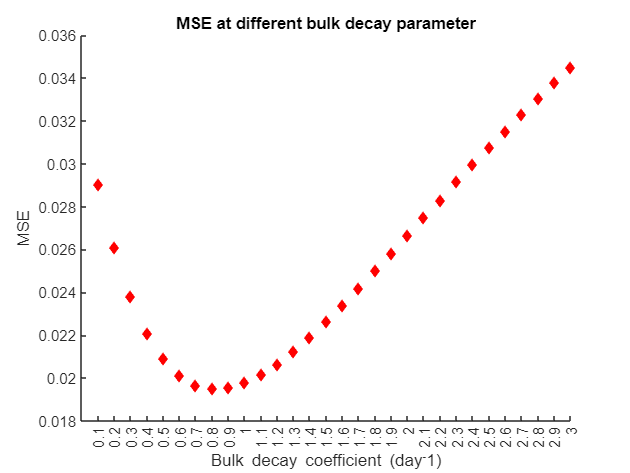


figure,
scatter(0.1:0.1:0.1*Iter3,mse_NoGroup3,'red','filled','diamond');
xlabel('Bulk decay coefficient (day{^-1})')
ylabel('MSE')
title('MSE at different bulk decay parameter')
xticks(0.1:0.1:0.1*Iter3);

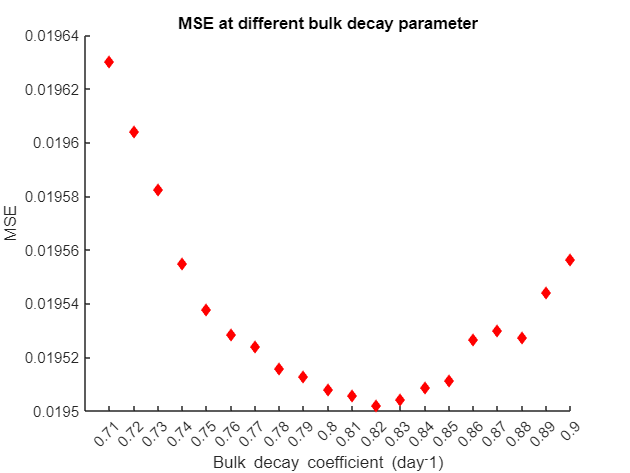

lambda_NoGroup4 = 0.71*ones(np,1);
Iter4 = 20;
mse_NoGroup4 = zeros(1,Iter4);

tic;
for i = 1:Iter4
    for j = 1:np
        calllib('epanet2','ENsetlinkvalue',j,6,-lambda_NoGroup4(j));
    end
    calllib('epanet2','ENopenQ');
    calllib('epanet2','ENinitQ',0);
    tleft4=1; Sim_NoGroup4=[]; 
    t = 0;
    while (tleft4>0)
        [errcode, t] = calllib('epanet2','ENrunQ',t);
        for k = 1:size(Obs_train,1)
            [errcode, Sim_NoGroupk(k,1)] = calllib('epanet2','ENgetnodevalue',Junction_SelectIdx(k),12,0);
        end
        Sim_NoGroup4 = [Sim_NoGroup4, Sim_NoGroupk];
        [errcode, tleft4] = calllib('epanet2','ENnextQ',tleft4);
    end
    calllib('epanet2','ENcloseQ');
    Sim_NoGroup4 = Sim_NoGroup4(:,2*96+1:3*96);
    mse_NoGroup4(i) = mse_function(Sim_NoGroup4,Obs_train);
    if mse_NoGroup4(i) < Tol
        break;
    else
        lambda_NoGroup4 = lambda_NoGroup4 + 0.01;
    end 
end
t_NoGroup4 = toc;

figure,
scatter(0.71:0.01:0.7+0.01*Iter4,mse_NoGroup4,'red','filled','diamond');
xlabel('Bulk decay coefficient (day{^-1})')
ylabel('MSE')
title('MSE at different bulk decay parameter')
xticks(0.7:0.01:0.7+0.01*Iter4);

mse_NoGroup_min = min(mse_NoGroup4);
lambda_NoGroup_Final = 0.71 + 0.01*(find(mse_NoGroup4 == mse_NoGroup_min)-1);
fprintf(['The lowest mse is %.4f, found at bulk decay coefficient equals' ...
    ' to %.2f.'],mse_NoGroup_min,lambda_NoGroup_Final);

The lowest mse is 0.0195, found at bulk decay coefficient equals to 0.82.

### Trial-and-Error calibration (roughness based group)

The trial and error calibration is also done based on the pipe roughness groups.

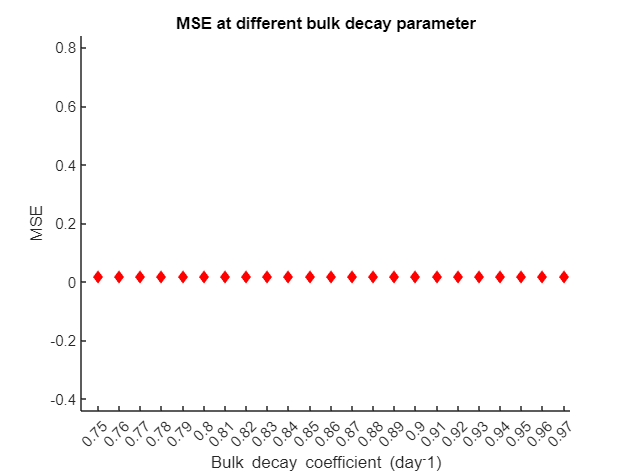

% Start from initial bulk decay coefficient of all 11 groups equals to -0.82
k_Group = lambda_NoGroup_Final*ones(length(R_Group),1);
lambda_Group = ones(length(R_CData),1);
Iter_Group = 40;

% Group1 (Valve group, not affect the bulk decay)
k_Group1 = k_Group;
k_Group1(1) = 0.62;
mse_Group1 = zeros(1,Iter_Group);
lambda_Group1 = Assignk(lambda_Group,k_Group1,R_CData);
for i = 1:Iter_Group
    mse_Group1(i) = TrialAndError(mse_function,lambda_Group1,Obs_train,Junction_SelectIdx,np);
    if mse_Group1(i) < Tol
        break;
    else
        k_Group1(1) = k_Group1(1) + 0.01;
        lambda_Group1 = Assignk(lambda_Group1,k_Group1,R_CData);
    end
end

figure,
scatter(0.62:0.01:0.62+0.01*(Iter_Group-1),mse_Group1,'red','filled','diamond');
xlabel('Bulk decay coefficient (day{^-1})')
ylabel('MSE')
title('MSE at different bulk decay parameter')
xticks(0.62:0.01:0.62+0.01*(Iter_Group-1));

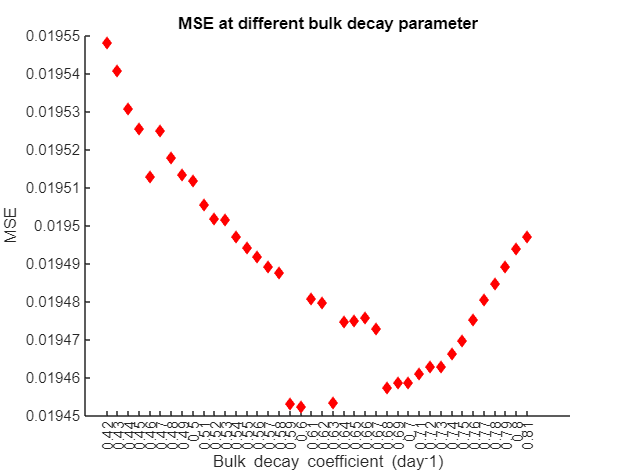

% Group2
k_Group2 = k_Group1;
k_Group2(1) = 0.82;
k_Group2(2) = 0.42;
mse_Group2 = zeros(1,Iter_Group);
lambda_Group2 = Assignk(lambda_Group,k_Group2,R_CData);
for i = 1:Iter_Group
    mse_Group2(i) = TrialAndError(mse_function,lambda_Group2,Obs_train,Junction_SelectIdx,np);
    if mse_Group2(i) < Tol
        break;
    else
        k_Group2(2) = k_Group2(2) + 0.01;
        lambda_Group2 = Assignk(lambda_Group2,k_Group2,R_CData);
    end
end

figure,
scatter(0.42:0.01:0.42+0.01*(Iter_Group-1),mse_Group2,'red','filled','diamond');
xlabel('Bulk decay coefficient (day{^-1})')
ylabel('MSE')
title('MSE at different bulk decay parameter')
xticks(0.42:0.01:0.42+0.01*(Iter_Group-1));

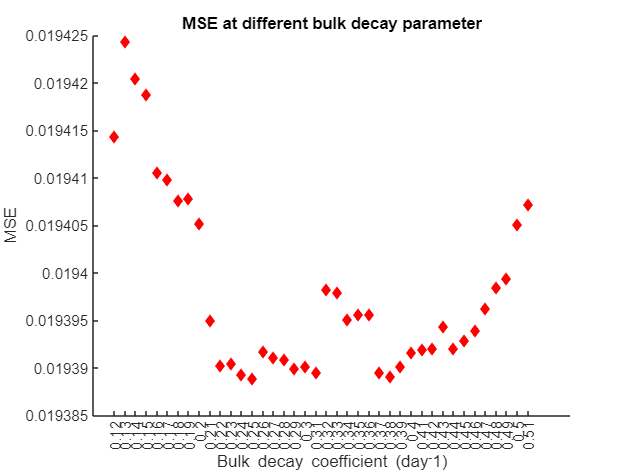

% Group3
k_Group3 = k_Group;
k_Group3(1) = 0.82;
k_Group3(2) = 0.60;
k_Group3(3) = 0.12;
mse_Group3 = zeros(1,Iter_Group);
lambda_Group3 = Assignk(lambda_Group,k_Group3,R_CData);
for i = 1:Iter_Group
    mse_Group3(i) = TrialAndError(mse_function,lambda_Group3,Obs_train,Junction_SelectIdx,np);
    if mse_Group3(i) < Tol
        break;
    else
        k_Group3(3) = k_Group3(3) + 0.01;
        lambda_Group3 = Assignk(lambda_Group,k_Group3,R_CData);
    end
end

figure,
scatter(0.12:0.01:0.12+0.01*(Iter_Group-1),mse_Group3,'red','filled','diamond');
xlabel('Bulk decay coefficient (day{^-1})')
ylabel('MSE')
title('MSE at different bulk decay parameter')
xticks(0.12:0.01:0.12+0.01*(Iter_Group-1));